# **Práctica 2: Funciones, Secuencias y Relaciones**

**Práctica:** 02

**Nombre: **Mateo Simbaña

**Fecha: 6** de enero del 2024

## 1. Arrays: vectores y matrices

Una matriz es un objeto rectangular que consta de filas y columnas, mientras que un vector es un tipo especial de matriz, que tiene solo una fila o una columna. 

### 1.1 Initializing vectors: explicit lists

x = [1 3 0 -1 5];
disp(x)

     1     3     0    -1     5



El comando `who `muestra el tamaño del vector:

whos

  Name       Size             Bytes  Class     Attributes

  A          3x5                120  double              
  B          5x9                360  double              
  a          1x3                 24  double              
  ans        1x3                 24  double              
  b          1x3                 24  double              
  c          1x5                 40  double              
  g          1x1                  8  double              
  r          1x7                 56  double              
  s          1x124              992  double              
  t          1x124              992  double              
  table      7x2                112  double              
  u          1x1                  8  double              
  x          1x5                 40  double              
  y          5x1                 40  double              
  z          5x1                 40  double              



Pueden ir comas, si lo desea:

x = [1 3 0 -1 5]

x =      1     3     0    -1     5


Además, se puede usar uno o más vectores dentro de otro:

a = [1 2 3];
b = [4 5];
c = [a -b]

c =      1     2     3    -4    -5


Para formar vectores es necesario tener en cuenta lo siguiente:

    ➤ Los elementos de la lista deben estar encerrados entre corchetes. 

    ➤ Los elementos de la lista deben estar separados por espacios o comas.

### 1.2 Initializing vectors: the colon operator

Se puede inicializar un vector con el operador dos puntos (:).

x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


x = 1:0.5:4

x =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000


x = 10:-1:1

x =     10     9     8     7     6     5     4     3     2     1


x = 1:2:6

x =      1     3     5


x = 0:-2:-5

x =      0    -2    -4


Para generar un vector vacío:

x = 1:0


x =

  1×0 empty double row vector



### 1.3 linspace

La función `linspace` se puede utilizar para inicializar un vector de valores igualmente espaciados. Por ejemplo:

linspace(0, pi/2, 10)

ans =          0    0.1745    0.3491    0.5236    0.6981    0.8727    1.0472    1.2217    1.3963    1.5708


### 1.4 Transposing vectors

Para generar los vectores de columna,se  deben transponer dichos vectores, es decir, intercambiar sus filas y columnas. Esto se hace con comillas simples o apóstrofe (’).

x = 1:5

x =      1     2     3     4     5


x'

ans =      1
     2
     3
     4
     5


Para crear un vector columna:

y = [1 4 8 0 -1]'

y =      1
     4
     8
     0
    -1


Para generar un vector fila de números aleatorios:

 r = rand (1,7)

r =     0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094


### 1.5 Matrices

Se crea una matriz similar a un vector, excepto que se usa un punto y coma para indicar el final de una fila, por ejemplo:

 a = [1 2 3; 4 5 6]

a =      1     2     3
     4     5     6


 a'

ans =      1     4
     2     5
     3     6


Se puede construir una matriz a partir de vectores de columna de la misma longitud.

x = 0:30:180;
table = [x' sin(x*pi/180)']

table =          0         0
   30.0000    0.5000
   60.0000    0.8660
   90.0000    1.0000
  120.0000    0.8660
  150.0000    0.5000
  180.0000    0.0000


Las matrices son el corazón de MATLAB:

a = [1 3 5; 2 4 6; 7 8 10]

a =      1     3     5
     2     4     6
     7     8    10


a'

ans =      1     2     7
     3     4     8
     5     6    10


a + 10

ans =     11    13    15
    12    14    16
    17    18    20


z = zeros(5,1)

z =      0
     0
     0
     0
     0


y = ones (5,1)

y =      1
     1
     1
     1
     1


A=[1:2:9; 0 -2 4 6 -1; ones(1,5)]

A =      1     3     5     7     9
     0    -2     4     6    -1
     1     1     1     1     1


B=[1 2 3 4 5 6 7 8 9; -1 -2 -3 -4 -5 -6 -7 9 2;
zeros(1,9); 3*ones(1,9); 9:-1:1]

B =      1     2     3     4     5     6     7     8     9
    -1    -2    -3    -4    -5    -6    -7     9     2
     0     0     0     0     0     0     0     0     0
     3     3     3     3     3     3     3     3     3
     9     8     7     6     5     4     3     2     1


### 1.6 Vertical motion under gravity 

Si se lanza una piedra verticalmente hacia arriba con una rapidez inicial **u = 60m/s**, su desplazamiento vertical s después de un tiempo t ha transcurrido está dado por la fórmula **s = **u*t - g/2*t.^2 , donde g es la aceleración debida a gravedad. Se ha ignorado la resistencia del aire. Nos gustaría calcular el valor de s durante un período de unos **12.3 segundos **a intervalos de **0.1 segundos**, y para trazar el gráfico de distancia-tiempo sobre este período. 

El plan de estructura para este problema es el siguiente: 

    1. Asigne los datos (g, u and t) a las variables de MATLAB. 

    2. Calcule el valor de s según la fórmula. 

    3. Trace la gráfica de s contra t. 

    4. Detener.

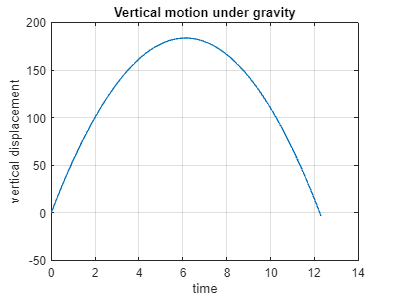

% Vertical motion under gravity
g = 9.8; % acceleration due to gravity
u = 60; % initial velocity (meters/sec)
t = 0 : 0.1 : 12.3; % time in seconds
s = u * t - g / 2 * t .^ 2; % vertical displacement in meters
plot(t, s), title( 'Vertical motion under gravity' ),
xlabel( 'time' ), ylabel( 'vertical displacement' ), grid

disp( [t' s'] ) % display a table

         0         0
    0.1000    5.9510
    0.2000   11.8040
    0.3000   17.5590
    0.4000   23.2160
    0.5000   28.7750
    0.6000   34.2360
    0.7000   39.5990
    0.8000   44.8640
    0.9000   50.0310
    1.0000   55.1000
    1.1000   60.0710
    1.2000   64.9440
    1.3000   69.7190
    1.4000   74.3960
    1.5000   78.9750
    1.6000   83.4560
    1.7000   87.8390
    1.8000   92.1240
    1.9000   96.3110
    2.0000  100.4000
    2.1000  104.3910
    2.2000  108.2840
    2.3000  112.0790
    2.4000  115.7760
    2.5000  119.3750
    2.6000  122.8760
    2.7000  126.2790
    2.8000  129.5840
    2.9000  132.7910
    3.0000  135.9000
    3.1000  138.9110
    3.2000  141.8240
    3.3000  144.6390
    3.4000  147.3560
    3.5000  149.9750
    3.6000  152.4960
    3.7000  154.9190
    3.8000  157.2440
    3.9000  159.4710
    4.0000  161.6000
    4.1000  163.6310
    4.2000  165.5640
    4.3000  167.3990
    4.4000  169.1360
    4.5000  170.7750
    4.6000  172.3160
    4.7000  1

## 2. Operators, expressions and statements

Las expresiones se construyen a partir de una variedad de cosas, como números, variables y operadores.

Lo que básicamente hace es evaluar expresiones, como:

`u*t - g/2*t.^2 `

y ejecutar (llevar a cabo) declaraciones, como:

`balance = balance + interest`

### 2.1 Numbers

Los números pueden ser representados en notación científica:

Por ejemplo:

- 1.2345 × 10^9

1.2345e9

ans = 1.2345e+09

- 0.000000001

1e-9

ans = 1.0000e-09

#### Ejercicios:

- Ingrese los siguientes números en el símbolo del sistema en notación científica.

1.234 × 10^5, − 8.765 × 10^−4, 10^−15, − 10^12 .

1.234e5

ans = 123400

-8.765e-4

ans = -8.7650e-04

10e-15

ans = 1.0000e-14

-10e12

ans = -1.0000e+13

### 2.2 Data types

Operaciones aritméticas entre dos escalares:

- **Adición:** a + b

- **Sustracción:** a - b

- **Multiplicación:** a * b

- **División derecha:** a / b

- **División izquierda:** a \ b, es decir b / a

- **Potencia:** a ^ b

### 2.3 Precedence of operators

Prioridad de las operaciones aritméticas:

- Paréntesis

- Potencia, de izquierda a derecha

- Multiplicación y división, de izquierda a derecha

- Adición y sustracción, de izquierda a derecha

#### Ejercicios:

- Evaluar las siguientes expresiones de MATLAB antes de comprobar las respuestas en MATLAB:

1 + 2 * 3

ans = 7

4 / 2 * 2

ans = 4

1+2 / 4

ans = 1.5000

1 + 2\4

ans = 3

2*2 ^ 3

ans = 16

2 * 3 \ 3

ans = 0.5000

2 ^ (1 + 2)/3

ans = 2.6667

1/2e-1

ans = 5

          2. Utilizar MATLAB para evaluar las siguientes expresiones.

1 / (2*3)

ans = 0.1667

2 ^ (2 * 3)

ans = 64

1.5e-4 + 2.5e-2

ans = 0.0252

### 2.4 The colon operator

El operador de dos puntos tiene una precedencia menor que +, como se muestra a continuación:

1+1:5

ans =      2     3     4     5


Operadores aritméticos que operan elemento por elemento en matrices:

- **Multiplicación:** .*

- **División derecha: **./

- **División izquierda:** .\

- **Potencia: **.^

1+[1:5]

ans =      2     3     4     5     6


El valor 1 se suma a cada elemento del vector 1:5.

### 2.5 The transpose operator

El operador de transposición tiene la máxima prioridad. Intentar:

1:5'

ans =      1     2     3     4     5


Primero se transpone el 5 (¡dentro de sí mismo ya que es un escalar!), y luego se forma un vector fila. Se utilizan corchetes si se desea transponer todo el vector:

[1:5]'

ans =      1
     2
     3
     4
     5


### 2.6 Arithmetic operations on arrays

a = [2 4 8];
b = [3 2 2];
a .* b

ans =      6     8    16


a ./ b

ans =     0.6667    2.0000    4.0000


a + b

ans =      5     6    10


a - b

ans =     -1     2     6


3.*a

ans =      6    12    24


a.^2

ans =      4    16    64


Una aplicación común de la multiplicación elemento por elemento es encontrar el producto escalar de dos v

ectores x e y.

La función `sum(z)` de MATLAB encuentra la suma de los elementos del vector `z`, por lo que la declaración `sum(a .* b)` encontrará el producto escalar de `a `y `b.`

sum(a.*b)

ans = 30

#### Ejercicios:

Utilizar operaciones de matriz MATLAB para hacer lo siguiente:

         1. Suma 1 a cada elemento del vector [2 3 -1].

 1 + [2 3 -1]

ans =      3     4     0


         2. Multiplica cada elemento del vector [1 4 8] por 3.

3 * [1 4 8]

ans =      3    12    24


         3. Encuentre el producto matricial de los dos vectores [1 2 3] y [0 -1 1].

[1 2 3] .* [0 -1 1]

ans =      0    -2     3


         4. Eleva al cuadrado cada elemento del vector [2 3 1].

[2 3 1] .^ 2

ans =      4     9     1


### 2. 7 Expressions

Una expresión es una fórmula que consta de variables, números, operadores y nombres de funciones. Una expresión se evalúa cuando la ingresa en el símbolo del sistema MATLAB, por ejemplo:

2 * pi

ans = 6.2832

### 2. 8 Statements 

Las declaraciones de MATLAB suelen tener la forma:

`variable = expresión`

`Por ejemplo:`

% s = u * t - g / 2 * t.^2

Cualquier línea que ingrese en la ventana de comandos o en un programa que MATLAB acepte es una declaración, por lo que una declaración podría ser una asignación, un comando o simplemente una expresión, por ejemplo:

x = 29; % asignación
clear % comando
pi/2 % expresión

ans = 1.5708

### 2.9 Vectorization of formulae

Con las operaciones de matriz, se puede evaluar fácilmente una fórmula repetidamente para un gran conjunto de datos. Esta es una de las funciones más útiles y potentes de MATLAB, y siempre se debe buscar formas de aprovecharla.

Por ejemplo, the calculation of compound interest. An amount of money A invested over a period of *n* years with an annual interest rate of *r *grows to an amount `A(1 +r) ^ n`. Suppose we want to calculate final balances for investments of $750, $1000, $3000, $5000 and $11 999, over 10 years, with an interest rate of 9 percent. The following program (`intcomp.m`) uses array operations on a vector of initial investments to do this

format bank
A = [750 1000 3000 5000 11999];
r = 0.09;
n = 10;
B = A*(1 + r)^n;
disp([A' B'])

        750.00       1775.52
       1000.00       2367.36
       3000.00       7102.09
       5000.00      11836.82
      11999.00      28406.00



## 3. Repeating with `for`

La repetición:

for i = 1:5, disp(i), end

          1.00

          2.00

          3.00

          4.00

          5.00



for i = 1:3, disp(i), end

          1.00

          2.00

          3.00



for i = 1:0, disp(i), end

#### 3.1 Square roots with Newton’s method 

La raíz cuadrada x de cualquier número positivo a se puede encontrar usando solo las operaciones aritméticas de suma, resta y división con el método de Newton. Este es un procedimiento iterativo (repetitivo) que entrega una suposición inicial. 

El plan estructural:

         1. Inicializar a

         2. Inicializar x a a/2

         3. Repetir 6 veces (digamos), reemplazar x por (x + a/x)/2, mostrar x

         4. Detener.

a = 2;
x = a/2;
disp(['The approach to sqrt(a) for a = ', num2str(a)])

The approach to sqrt(a) for a = 2


for i = 1:6
 x = (x + a / x) / 2;
 disp( x )
end

          1.50

          1.42

          1.41

          1.41

          1.41

          1.41



disp( 'Matlab''s value: ' )

Matlab's value: 


disp( sqrt(2) )

          1.41



#### 3.2 Factorials!

n = 10;
fact = 1;
for k = 1:n
 fact = k * fact;
 disp( [k fact] )
end

          1.00          1.00

          2.00          2.00

          3.00          6.00

          4.00         24.00

          5.00        120.00

          6.00        720.00

          7.00       5040.00

          8.00      40320.00

          9.00     362880.00

         10.00    3628800.00



### 4. Decisions

La función `rand `de MATLAB genera un número aleatorio en el rango 0-1.

r = rand

r =           0.75


if r > 0.5 
    disp( 'greater indeed' ), end

greater indeed


Operadores relacionales:

- **Menor que: **<

- **Menor o igual que:** <=

- **Igual: ==**

- **No es igual:** ~=

- **Mayor que:** >

- **Mayor o igual que:** >=